# Cessna Citation 500

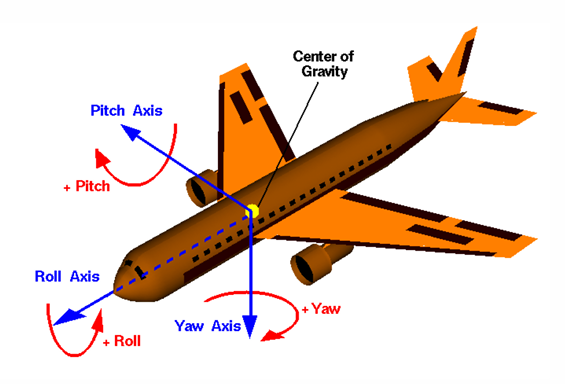

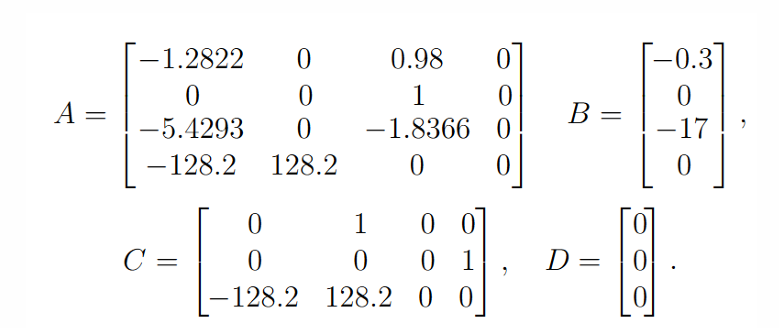

## Problem:

The elevation angle (rad) is the only controllable **input** 𝑢 ∈ ℝ. 

The **outputs** 𝑦 =  [1, 𝑦2,𝑦3 ]^𝑇 ∈ ℝ^3 are: 

• 𝑦1 the angle of pitch (rad) 

• 𝑦2 altitude (m) 

• 𝑦3 the rate of change in altitude(m/s). 

The **states** of the system 𝑥 = [x1, 𝑥2,𝑥3,𝑥4]^𝑇 ∈ ℝ^4 are: 

 • 𝑥1 the angle of roll (rad), 

 • 𝑥2 the angle of pitch (rad) 

• 𝑥3 the rate of change of the pitch angle (rad/s) 

• 𝑥4 the altitude (m).

%Definizione Matrici di stato e del sistema

A = [-1.2822, 0, 0.98, 0;
     0, 0, 1, 0;
     -5.4293, 0, -1.8366, 0;
     -128.2, 128.2, 0, 0];

B = [-0.3; 0; -17; 0];

C = [0, 1, 0, 0;
     0, 0, 0, 1;
     -128.2, 128.2, 0, 0];

%D = [0; 0; 0];
D = zeros(3,1);

plant = ss(A,B,C,D);

### Contraints:

The elevation angle 𝑢 is limited to ±15° (±0.262 𝑟𝑎𝑑), and the rate of change of elevation Δ𝑢 be limited to ±30°(0.524𝑟𝑎𝑑/𝑠). 

These constraints are imposed by the physical design limitations of the vehicle. 

For the comfort of passengers, the pitch angle 𝑦1 should be limited to  ±20° (±0.349𝑟𝑎𝑑).

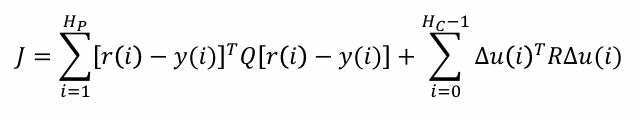

a) Assume that at time t=0, all initial states are zero (the altitude will be considered 0 with "relative altitude" with reference to 5000m). The parameters for the simulation are:

Ts = 0.5; %[s] tempo di campionamento
Tf = 20; %[s] tempo di simulazione
Hp = 10; %(5 s) orizzonte di predizione
Hc = 3; %(3 s) orizzonte di controllo

mpcobj = mpc(plant, Ts);

-->"PredictionHorizon" is empty. Assuming default 10.
-->"ControlHorizon" is empty. Assuming default 2.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 y3 


mpcobj.PredictionHorizon = Hp;
mpcobj.ControlHorizon = Hc;


% Pesi unitari (iniziali) su tutte e 3 le uscite perchè matlab di default dà priorità solo a y1
mpcobj.Weights.OutputVariables(1)=1;
mpcobj.Weights.OutputVariables(2)=1;
mpcobj.Weights.OutputVariables(3)=3; % la nostra Q se leggiamo avanti deve essere Q=diag([1,1,3]) e l'ho già impostata qua
% Questo tuning penalizza l'errore sul rateo di altitudine, portando a un transitorio più smorzato per l'altitudine.

% Vincolo su u (Elevation Angle): +/- 15 gradi = +/- 0.262 rad
mpcobj.ManipulatedVariables.Min=deg2rad(-15); %deg2rad ha input i gradi e restituisce il valore in radianti
mpcobj.ManipulatedVariables.Max=deg2rad(15);

% Vincolo su Δu (Rateo): +/- 30 gradi/s = +/- 0.524 rad/s
% SCALATO per Ts: RateMax = (Rate Max Continuo) * Ts
mpcobj.ManipulatedVariables.RateMin=deg2rad(-30)*Ts;
mpcobj.ManipulatedVariables.RateMax=deg2rad(30)*Ts;

% Vincolo su y1 (Pitch Angle): +/- 20 gradi = +/- 0.349 rad
mpcobj.OutputVariables(1).Min=deg2rad(-20);
mpcobj.OutputVariables(1).Max=deg2rad(20);

- Simulate the response to a 40m step in the altitude set-point. Is there any constraint action?

- Increse the desired altitude gradually from 40m to 400m. When do the constraints start to act? What is the effect of the magnitude of the change in desired altitude?

- Suppose the desired altitude is set to 400m. Change the weights on the tracking errors to Q = diag(1,1,3). This means that the rate of error on the rate of change in altitude is penalized more during optimization. What is the effect of the new weights?

xk=mpcstate(mpcobj);

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
   Assuming no disturbance added to measured output #2.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


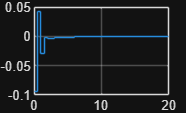

t= 0:Ts:Tf;
N=length(t);
y_history=[];
u_history=[];
ref=[0;40;0];

for i=1:N
y=C*xk.Plant;
u=mpcmove(mpcobj, xk, y, ref);
y_history=[y_history; y'];
u_history=[u_history; u];
ref(2)=ref(2)+360/40;
end

%Plotting
figure(1);
stairs(t, u_history); %stairs() è usato per discretizzare il grafico
grid on;

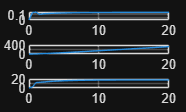


figure(2);
for i=1:3
subplot(3,1,i);
plot(t, y_history(:,i));
grid on;
end

b) In the previous point, the rate of change of altitude was not constrained. Suppose we constrain it to 30 m/s. Simulate the response of the system to a change of altitude of 400m.

- Interpret the result obtained.

- Make the appropriate changes so that the desired height is reached more quickly. Discuss the effects of the constraints on the rate of change of altitude.

% Reset e Configurazione iniziale (come nel tuo stile)
mpcobj.Weights.OutputVariables = [1, 1, 1]; % Reset pesi

% Vincoli precedenti (già impostati, ma ribaditi per chiarezza)
u_max_rad = deg2rad(15);
mpcobj.ManipulatedVariables.Min = -u_max_rad;
mpcobj.ManipulatedVariables.Max = u_max_rad;
Delta_u_max = deg2rad(30) * Ts; % SCALATO PER Ts
mpcobj.ManipulatedVariables.RateMin = -Delta_u_max;
mpcobj.ManipulatedVariables.RateMax = Delta_u_max;

% NUOVO: Vincolo sull'Uscita y3 (Altitude Change Rate) +/- 30 m/s
mpcobj.OutputVariables(3).Min = -30;
mpcobj.OutputVariables(3).Max = 30;

% Inizializzazione Simulazione
xk = mpcstate(mpcobj);

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
   Assuming no disturbance added to measured output #2.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


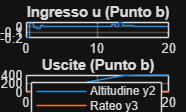

t = 0:Ts:Tf;
N = length(t);
y_history = [];
u_history = [];

% Riferimento Costante a 400m
ref = [0; 400; 0]; 

% Ciclo di Simulazione (Tuo stile)
for i = 1:N
    % Misura dell'uscita dal modello interno (xk.Plant)
    y = C * xk.Plant; 
    
    % Calcolo azione di controllo
    u = mpcmove(mpcobj, xk, y, ref);
    
    % Salvataggio dati
    y_history = [y_history; y'];
    u_history = [u_history; u];
    
    % Nota: Non aggiorno ref in modo incrementale perché è un gradino unico
end

% Plotting
figure(3);
subplot(2,1,1);
stairs(t, u_history); grid on; title('Ingresso u (Punto b)');
subplot(2,1,2);
plot(t, y_history(:,2)); grid on; hold on;
plot(t, y_history(:,3)); % Mostra anche y3 per vedere il vincolo
legend('Altitudine y2', 'Rateo y3'); title('Uscite (Punto b)');

c)  Suppose that during navigation a turbulence occurs that modeling looks like an impulsive disturbance on the altitude change of 5 m/s. Suppose that this turbulence appears at second 5 and lasts 5 seconds. Add this turbulence to the simulation with a desired altitude of 400 m and a constraint on the altitude change of 30 m/s.

- What is the behavior of the system?

- Gradually increase the amplitude of disturbance. What happens if the disturbance is too large?

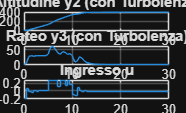

% Estendiamo il tempo per vedere l'assestamento
Tf_c = 30; 
t = 0:Ts:Tf_c;
N = length(t);

% Reinizializzazione stati e storici
xk = mpcstate(mpcobj);
y_history = [];
u_history = [];
ref = [0; 400; 0];

% Definizione Disturbo
disturb_val = 5; % 5 m/s
t_start = 5;
t_end = 10;

for i = 1:N
    % Calcolo uscita nominale
    y = C * xk.Plant;
    
    % Aggiunta Disturbo su y(3) se siamo nell'intervallo temporale
    current_time = (i-1)*Ts;
    if current_time >= t_start && current_time < t_end
        y(3) = y(3) + disturb_val;
    end
    
    % Calcolo azione di controllo (MPC reagisce al disturbo misurato in y)
    u = mpcmove(mpcobj, xk, y, ref);
    
    % Salvataggio
    y_history = [y_history; y'];
    u_history = [u_history; u];
end

% Plotting
figure(4);
subplot(3,1,1);
plot(t, y_history(:,2)); grid on; title('Altitudine y2 (con Turbolenza)');
subplot(3,1,2);
plot(t, y_history(:,3)); grid on; title('Rateo y3 (con Turbolenza)');
subplot(3,1,3);
stairs(t, u_history); grid on; title('Ingresso u');

d)  Suppose that the gain between elevation angle and altitude change ratio has been modeled incorrectly, i.e. such that the model used by the MPC controller underestimates this gain by 15%.

- run the simulation with a set point that requires a 400m change in altitude, with the altitude change ratio constrained to 30m/s and no noise in the output.

- Gradually increase the percentage of modelling error. What happens?

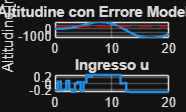

% Scenario: Setpoint 400m, Vincolo su rateo +/- 30 m/s, NO rumore.
% Errore: Il modello sottostima il guadagno (il plant reale è più "forte").

% 1. Configurazione MPC (Modello Nominale)
% Usiamo i vincoli del punto b (rateo)
mpcobj.OutputVariables(3).Min = -30;
mpcobj.OutputVariables(3).Max = 30;
% Reset pesi
mpcobj.Weights.OutputVariables = [1, 1, 1]; 

% 2. Creazione del "Mondo Reale" (Plant con errore +15%)
error_factor = 1.15; 
A_real = A * error_factor;
B_real = B * error_factor;
C_real = C; 
D_real = D;


% Creiamo prima l'oggetto SS continuo, poi discretizziamo
sys_real_cont = ss(A_real, B_real, C_real, D_real);
sys_real_disc = c2d(sys_real_cont, Ts);
% Estraiamo le matrici discrete A e B per il calcolo manuale
[Ad_real, Bd_real, ~, ~] = ssdata(sys_real_disc);

% 3. Inizializzazione Variabili
Tf_d = 20;
t = 0:Ts:Tf_d;
N = length(t);

xk = mpcstate(mpcobj);   % Stato stimato dal controllore (basato sul modello nominale)
x_real = zeros(4,1);     % Stato vero del sistema (parte da 0)
y_history = [];
u_history = [];
ref = [0; 400; 0];       % Riferimento costante 400m

% 4. Ciclo di Simulazione
for i = 1:N
    % A. Misura: Leggiamo l'uscita dal sistema REALE (y = Cx + Du)
    % Nota: Usiamo le matrici reali continue C e D (che solitamente non cambiano)
    y_measured = C_real * x_real + D_real * 0; % (Assumendo D*u trascurabile o u passo prec.)
    
    % B. Controllo: L'MPC calcola u usando il suo modello interno e la y reale
    u = mpcmove(mpcobj, xk, y_measured, ref);
    
    % C. Evoluzione: Il sistema REALE evolve con le matrici discrete REALI
    x_real = Ad_real * x_real + Bd_real * u;
    
    % Salvataggio
    y_history = [y_history; y_measured'];
    u_history = [u_history; u];
end

% 5. Plotting 
figure(5);
subplot(2,1,1);
plot(t, y_history(:,2), 'LineWidth', 1.5); grid on; hold on;
yline(400, 'r--');
title(['Punto d: Altitudine con Errore Modellazione (+15%)']);
ylabel('Altitudine [m]');
subplot(2,1,2);
stairs(t, u_history, 'LineWidth', 1.5); grid on;
title('Ingresso u');

e)  Consider a scenario without disturbances and constraints on the altitude change, with a set-point that requires an altitude change of 400 m.

- Can the stability of the open-loop system be determined through the eigenvalues of A? What can be said about its stability?

- Decrease the prediction horizon. What happens if it is too short?

% --- PARTE 1: Analisi Stabilità Open-Loop ---
eigenvalues_A = eig(A);
disp('--- Punto e: Autovalori della matrice A ---');

--- Punto e: Autovalori della matrice A ---


disp(eigenvalues_A);

   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.5594 + 2.2900i
  -1.5594 - 2.2900i




% Se Re(lambda) > 0 -> Instabile.
% Se Re(lambda) < 0 -> Asintoticamente Stabile.
% Se c'è un autovalore nell'origine (0) -> Semplicemente stabile (o instabile se molteplice).
% Nel caso di un aereo, spesso c'è un polo nell'origine (integratore posizione) 
% o modi instabili (es. spirale) che richiedono feedback.

% --- PARTE 2: Orizzonte Corto (Short Prediction Horizon) ---
% Scenario: Setpoint 400m, NO vincoli rateo (rilassati), NO disturbi.

mpc_short = mpcobj; % Copia oggetto base

% Rilasso il vincolo su y3 come richiesto ("without constraints on altitude change")
mpc_short.OutputVariables(3).Min = -inf;
mpc_short.OutputVariables(3).Max = inf;

% Riduco drasticamente l'orizzonte di predizione
Hp_short = 3; % Valore molto basso (il default era 10)
mpc_short.PredictionHorizon = Hp_short;
% Nota: Hc deve essere <= Hp, quindi riduco anche Hc se necessario
mpc_short.ControlHorizon = 2; 

% Inizializzazione Simulazione Orizzonte Corto
xk = mpcstate(mpc_short);

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
   Assuming no disturbance added to measured output #2.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


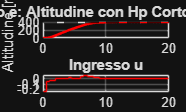

% Discretizzazione del modello NOMINALE (non c'è errore qui)
plant_d = c2d(plant, Ts); 
Ad = plant_d.A; Bd = plant_d.B; 
%[Ad, Bd, Cd, Dd] = ssdata(plant_d);

x = zeros(4,1);
y_history_short = [];
u_history_short = [];
ref = [0; 400; 0];

% Ciclo Simulazione
for i = 1:N
    y = C * x;
    u = mpcmove(mpc_short, xk, y, ref);
    x = Ad * x + Bd * u;
    
    y_history_short = [y_history_short; y'];
    u_history_short = [u_history_short; u];
end

% Plotting
figure(6);
subplot(2,1,1);
plot(t, y_history_short(:,2), 'r', 'LineWidth', 1.5); grid on; hold on;
yline(400, 'k--');
title(['Punto e: Altitudine con Hp Corto (Hp = ' num2str(Hp_short) ')']);
ylabel('Altitudine [m]');
subplot(2,1,2);
stairs(t, u_history_short, 'r'); grid on;
title('Ingresso u');